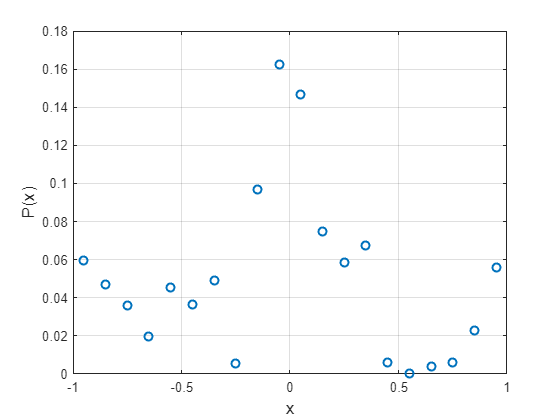

% ----------------------------------------------
% This program formulates the minimimal variance mechanism problem into a
% linear programing problem, and solves it using the built-in solver in Matlab.
% Comments are adquent in the code. 
% If you have any question,
% please feel free to contact Fei Wei at feiwei@nus.edu.sg
% ----------------------------------------------

close all
clear


% eps = 2; % privacy parameter
delta = 0; % privacy parameter
r=0.5; % geometric series constant
axRatio = 2; %the ratio amax/(xmax-xmin)

xmax = 1;
N = 20; % Total number of bins in [-xmax,xmax]
x_bin_size = 2*xmax/N;
x_grid = linspace(-xmax+0.5*x_bin_size,xmax-0.5*x_bin_size,N);

% We assign a distribution to X\in x_grid
% In the write-up, this is the data distribution

% x_P = ones(1,N)/N; % Uniform distribution

x_P = readmatrix("estimated_freq_2_GAUSSIAN_100000_-5_5_1_0.1_0.25.csv");
x_P = x_P'./ sum(x_P);

figure
plot(x_grid,x_P,'o',LineWidth=1.5);
xlabel("x",FontSize=13);
ylabel("P(x)",FontSize=13);
grid on


% [totalVariance,pMatrix] = opt_variance(eps,r,axRatio,x_grid,x_P);

% For testing, we sample a sequence of epsilon values
eps_grid = exp(linspace(0,log(8),20));

% The variance of optimal mechanism
VarOpt = zeros(1,length(eps_grid));
VarOptWorst = zeros(1,length(eps_grid));
for i = 1:length(eps_grid)
    [varVector,pMatrix,a_grid] =... 
        opt_variance(eps_grid(i),delta,r,axRatio,x_grid,x_P);
    VarOpt(i) = x_P*varVector;
    VarOptWorst(i) = max(varVector);
end

--------------------------------
eps = 1.000000, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-14 *

    0.1521   -0.0268    0.0282   -0.0133    0.2251    0.0301    0.0235    0.0261    0.0811    0.0132   -0.0125   -0.0184    0.0728    0.0075    0.0103   -0.0479   -0.0124   -0.0186    0.0004    0.0143


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     2.4195    2.8235    2.9105    2.8459    2.7298    2.5758    2.3846    2.3548    2.3378    2.3191    2.3133    2.3185    2.3128    2.4958    2.6777    3.3557    2.9506    3.0103    2.9815    2.7020


--------------------------------
eps = 1.115658, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.1147    0.0355   -0.0216    0.0731   -0.0237   -0.0008    0.0383    0.2193   -0.0153    0.1829    0.2196    0.0870    0.0643   -0.0288    0.0845   -0.0686   -0.0335    0.0520    0.1304   -0.2680


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     2.1976    2.4882    2.5143    2.4467    2.3181    2.1480    2.0948    2.0208    1.9489    1.9299    1.9290    1.9284    1.9977    2.0938    2.2928    2.9764    2.5971    2.6802    2.6808    2.5353


--------------------------------
eps = 1.244693, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-14 *

   -0.0042   -0.0130   -0.0016    0.3854    0.0732   -0.0147   -0.0041   -0.0063   -0.0012   -0.0015    0.0468    0.0422    0.0051   -0.0060    0.0015    0.0056   -0.0176   -0.0237   -0.0245    0.0370


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     1.8736    2.0804    2.0890    2.0100    1.8781    1.8389    1.7788    1.7039    1.6065    1.5780    1.5683    1.6061    1.6748    1.7401    1.9338    2.1409    2.2563    2.3644    2.4134    2.3665


--------------------------------
eps = 1.388651, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

    0.5619   -0.0442    0.1715   -0.1077    0.0378   -0.3542    0.1353    0.0854    0.1703   -0.1256   -0.4149   -0.3238   -0.0866    0.1325    0.3260   -0.0820    0.0334   -0.1989   -0.1063    0.0930


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     1.5195    1.6442    1.6274    1.6100    1.5896    1.5357    1.4735    1.3975    1.2995    1.2627    1.2530    1.3188    1.3883    1.4471    1.5598    2.3241    1.8957    2.0312    2.1317    2.1900


--------------------------------
eps = 1.549260, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

    0.3260    0.0734    0.1168   -0.2864   -0.0629    0.2072    0.0562    0.0497   -0.2364    0.0759   -0.0169   -0.0132    0.1972   -0.0686   -0.1894   -0.3021    0.1165    0.0926   -0.1376   -0.3516


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     1.4721    1.4423    1.3562    1.3403    1.3001    1.2517    1.1952    1.1254    1.0373    0.9692    0.9692    1.0387    1.1082    1.1771    1.2547    1.7450    1.3419    1.4715    1.5768    1.6514


--------------------------------
eps = 1.728444, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-14 *

   -0.1206   -0.0084   -0.0015    0.0049    0.0006   -0.0058    0.0044   -0.0241    0.0000   -0.0493    0.0453    0.0001    0.0093    0.0054    0.0012   -0.0025    0.0120    0.0333    0.0296    0.0151


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     1.2474    1.1242    1.1089    1.0859    1.0496    1.0061    0.9470    0.8775    0.7878    0.7028    0.7348    0.8139    0.8936    0.9723    1.0444    1.3043    1.1383    1.1605    1.1613    1.2638


--------------------------------
eps = 1.928352, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.0892    0.0197   -0.0535   -0.0024   -0.0099    0.0492   -0.0015    0.0431   -0.0447   -0.0661    0.0789    0.0150    0.1186   -0.0657    0.4333    0.3787    0.0072   -0.0902    0.1102   -0.1488


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.9422    0.9051    0.8769    0.8475    0.8175    0.7702    0.7203    0.6604    0.5804    0.5004    0.5504    0.6197    0.6897    0.7687    0.8387    1.3647    0.9389    0.9689    0.9814    1.0027


--------------------------------
eps = 2.151381, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-14 *

   -0.0183    0.0184   -0.0684   -0.0023    0.0119   -0.0055    0.0057    0.0060   -0.0066    0.0458    0.0068   -0.0765   -0.1463    0.0386    0.0003    0.0072   -0.0110   -0.0150   -0.0035    0.0286


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.7595    0.7211    0.6946    0.6680    0.6313    0.5944    0.5544    0.5095    0.4495    0.3846    0.3784    0.4290    0.4890    0.5490    0.6190    1.0392    0.7095    0.7295    0.7449    0.7549


--------------------------------
eps = 2.400205, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.0857   -0.0964   -0.2401   -0.6158   -0.0584    0.0481   -0.0351    0.1165    0.0078    0.3569   -0.1165   -0.0343   -0.0278    0.0296   -0.0716   -0.0303    0.0195    0.0598   -0.0814    0.0590


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.5667    0.5367    0.5125    0.4825    0.4625    0.4347    0.3949    0.3549    0.2957    0.2763    0.2721    0.3321    0.3921    0.4421    0.5021    0.9277    0.5693    0.5829    0.5913    0.6013


--------------------------------
eps = 2.677808, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

    0.0317   -0.0084   -0.0590   -0.1140   -0.0231    0.0347   -0.0039   -0.0318    0.0549   -0.2652   -0.0087   -0.0878    0.0255    0.0214   -0.0202    0.0439   -0.0088   -0.0387   -0.0789   -0.1370


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.4328    0.4153    0.3987    0.3887    0.3587    0.3287    0.2987    0.2587    0.2087    0.1987    0.1966    0.2193    0.2693    0.3193    0.3693    0.7413    0.4292    0.4453    0.4453    0.4462


--------------------------------
eps = 2.987518, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

    0.0143    0.1883    0.0585   -0.0113   -0.0017    0.0254    0.0029    0.0022    0.0205    0.0338    0.1036   -0.0230   -0.0435    0.0173   -0.0190   -0.1370   -0.0148   -0.0269   -0.0336   -0.2989


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.3222    0.3022    0.2922    0.2882    0.2682    0.2464    0.2144    0.1744    0.1495    0.1420    0.1420    0.1452    0.1852    0.2252    0.2733    0.9964    0.3360    0.3464    0.3464    0.3364


--------------------------------
eps = 3.333048, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

    0.0700    0.0548   -0.0209    0.0093   -0.1339   -0.0167    0.0029    0.0205    0.0686   -0.0115   -0.0045   -0.0138    0.0184   -0.0263   -0.0263   -0.0909   -0.0602    0.0142   -0.0715    0.0180


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.2400    0.2200    0.2100    0.1982    0.1782    0.1582    0.1324    0.1214    0.1036    0.0992    0.1020    0.1120    0.1235    0.1635    0.2035    0.8956    0.2642    0.2742    0.2642    0.2542


--------------------------------
eps = 3.718541, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

    0.0885   -0.0072   -0.0232   -0.0437   -0.0070   -0.0407    0.0033   -0.0026    0.0259   -0.0050    0.0058    0.0036   -0.0036    0.0313    0.0385   -0.1971   -0.0365    0.0113    0.0220    0.0185


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.1692    0.1676    0.1576    0.1483    0.1283    0.1047    0.0875    0.0857    0.0718    0.0632    0.0711    0.0776    0.0780    0.1080    0.1580    0.7271    0.1996    0.1996    0.1896    0.1796


--------------------------------
eps = 4.148620, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.0200    0.0771   -0.0128   -0.0013   -0.0057    0.0004   -0.0049    0.0172   -0.0420    0.1790    0.0008    0.0003   -0.0004   -0.0087   -0.0018    0.0809    0.0100    0.0199    0.0192    0.0169


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.1186    0.1186    0.1176    0.1091    0.0910    0.0684    0.0633    0.0574    0.0474    0.0444    0.0450    0.0511    0.0519    0.0587    0.0987    0.7277    0.1494    0.1494    0.1360    0.1260


--------------------------------
eps = 4.628441, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

    0.4509   -0.0072   -0.0061    0.3588   -0.0143    0.1370   -0.1102    0.0771   -0.0153   -0.1294   -0.0590   -0.0309    0.0468   -0.0631   -0.0921    0.7263   -0.2760    0.5542    0.0649   -0.5281


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.0786    0.0773    0.0767    0.0767    0.0567    0.0484    0.0440    0.0398    0.0298    0.0295    0.0295    0.0345    0.0348    0.0368    0.0768    0.6865    0.1150    0.1080    0.0980    0.0810


--------------------------------
eps = 5.163757, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.0229    0.0182    0.0217    0.0018    0.0062   -0.0443    0.0006    0.0090    0.0044   -0.0008    0.0002   -0.0170   -0.0655    0.0070   -0.0035   -0.1607   -0.0166   -0.0285    0.0048    0.0296


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.0487    0.0492    0.0581    0.0581    0.0381    0.0281    0.0245    0.0242    0.0199    0.0138    0.0182    0.0229    0.0229    0.0294    0.0694    0.6568    0.0994    0.0894    0.0794    0.0573


--------------------------------
eps = 5.760986, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

   -0.1111   -0.2198    0.1137    0.0205    0.0038    0.0694    0.2094    0.1710    0.0012    0.0183   -0.0309   -0.0525    0.0686    0.0446    0.0183    0.5220   -0.0991    0.1629   -0.1451    0.2579


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans = 1×20
    0.0341    0.0341    0.0341    0.0255    0.0202    0.0202    0.0139    0.0179    0.0089    0.0085    0.0092    0.0136    0.0188    0.0188    0.0310    0.6398    0.0710    0.0680    0.0498    0.0398


--------------------------------
eps = 6.427290, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1×20
1.0e-15 *

   -0.0194    0.0101    0.0032   -0.0096   -0.0323   -0.0060   -0.0115   -0.0635   -0.0001   -0.0990    0.0002    0.0006    0.0003   -0.0059    0.0271   -0.1599   -0.0157    0.0439   -0.0358   -0.0105


Distribution validity check (should be all ones):


ans = 1×20
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans = 1×20
    0.0239    0.0239    0.0226    0.0179    0.0140    0.0153    0.0072    0.0150    0.0050    0.0046    0.0049    0.0055    0.0065    0.0078    0.0261    0.6626    0.0661    0.0561    0.0360    0.0226


--------------------------------
eps = 7.170657, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1×20
1.0e-16 *

   -0.0036    0.0376    0.6322   -0.5275   -0.0057    0.0010   -0.0039   -0.0660   -0.4440   -0.0041    0.1692    0.0038    0.0100   -0.1633    0.1699    0.6335    0.0069   -0.0977    0.5072    0.0121


Distribution validity check (should be all ones):


ans = 1×20
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans = 1×20
    0.0110    0.0174    0.0087    0.0154    0.0054    0.0045    0.0037    0.0129    0.0029    0.0028    0.0030    0.0034    0.0040    0.0048    0.0248    0.5941    0.0288    0.0208    0.0208    0.0137


--------------------------------
eps = 8.000000, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1×20
1.0e-16 *

    0.0157    0.0022    0.0048   -0.0973    0.0095    0.0039   -0.0014   -0.2124    0.0207    0.0530    0.3972    0.2068   -0.3350    0.0080    0.0671    0.6676    0.0763   -0.1249   -0.0158   -0.0156


Distribution validity check (should be all ones):


ans = 1×20
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans = 1×20
    0.0054    0.0046    0.0038    0.0127    0.0027    0.0023    0.0019    0.0115    0.0015    0.0015    0.0017    0.0019    0.0022    0.0026    0.0160    0.6054    0.0119    0.0119    0.0119    0.0072


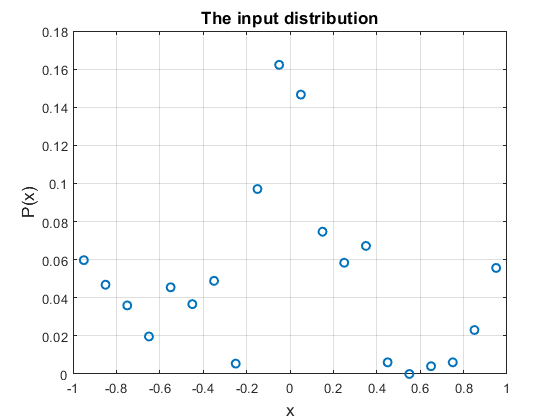

% The variance vector of Laplace mechanism
VarLaplace = zeros(1,length(eps_grid));
for i = 1:length(eps_grid)
    VarLaplace(i) = 8/(eps_grid(i))^2;
end

% The variance vector of Duchi mechanism
VarDuchi = zeros(1,length(eps_grid));
VarDuchiWorst = zeros(1,length(eps_grid));
var_duchi = @(ti,eps) ((exp(eps)+1)/(exp(eps)-1)).^2 - ti.^2;
for i = 1:length(eps_grid)
    temp = var_duchi(x_grid,eps_grid(i));
    VarDuchi(i) = temp *x_P';
    VarDuchiWorst(i) = max(temp);
end

% The variance vector of piece-wise mechanism
VarPiecewise = zeros(1,length(eps_grid));
VarPiecewiseWorst = zeros(1,length(eps_grid));
var_piecewise = @(ti,eps) ti.^2./(exp(eps/2)-1) + (exp(eps/2)+3)/3/(exp(eps/2)-1)^2;
for i = 1:length(eps_grid)
    temp = var_piecewise(x_grid,eps_grid(i));
    VarPiecewise(i) = temp *x_P';
    VarPiecewiseWorst(i) = max(temp);
end

% The variance vector of Hybrid mechanism
VarHybrid = zeros(1,length(eps_grid));
VarHybridWorst = zeros(1,length(eps_grid));
alpha = @(eps) sign(max(eps-0.61,0))*(1-exp(-eps/2));
var_hybrid = @(ti,eps) alpha(eps)*var_piecewise(ti,eps) + (1-alpha(eps))*var_duchi(ti,eps);
for i = 1:length(eps_grid)
    temp = var_hybrid(x_grid,eps_grid(i));
    VarHybrid(i) = temp *x_P';
    VarHybridWorst(i) = max(temp);
end

% The plots

figure;
plot(x_grid,x_P,'o',LineWidth=1.5);
title("The input distribution",FontSize=13);
xlabel("x",FontSize=13);
ylabel("P(x)",FontSize=13);
grid on

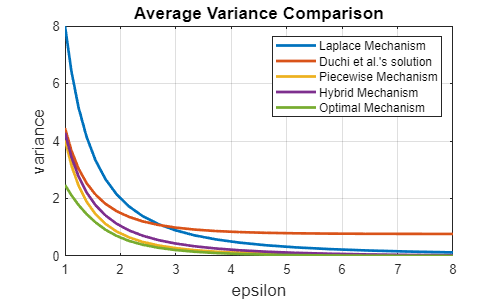

figure;
f = figure;
f.Position = [0 0 500 300];

plot(eps_grid,VarLaplace,LineWidth=2);
hold on
plot(eps_grid,VarDuchi,LineWidth=2);
hold on
plot(eps_grid,VarPiecewise,LineWidth=2);
hold on
plot(eps_grid,VarHybrid,LineWidth=2);
hold on
plot(eps_grid,VarOpt,LineWidth=2);

title("Average Variance Comparison",FontSize=13)
xlabel("epsilon",FontSize=13)
ylabel("variance",FontSize=13)
legend("Laplace Mechanism", "Duchi et al.'s solution",...
    "Piecewise Mechanism","Hybrid Mechanism","Optimal Mechanism")
grid on

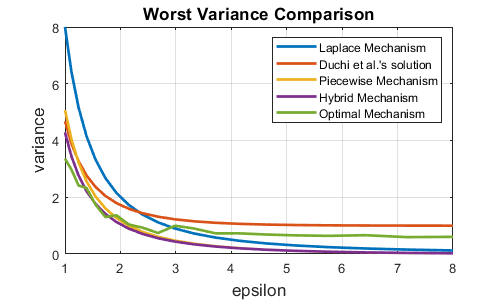

--------------------------------
eps = 2.000000, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.2603   -0.0950   -0.2166   -0.0134   -0.0023   -0.1943   -0.0103         0   -0.1153   -0.0761   -0.1952


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.8108    0.7446    0.6855    0.6194    0.5401    0.4410    0.5401    0.6194    0.6855    0.7446    0.8108


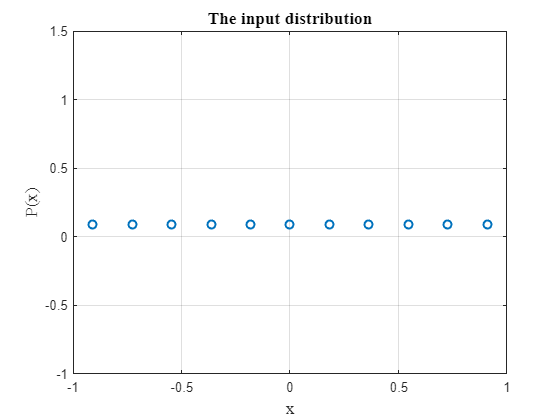

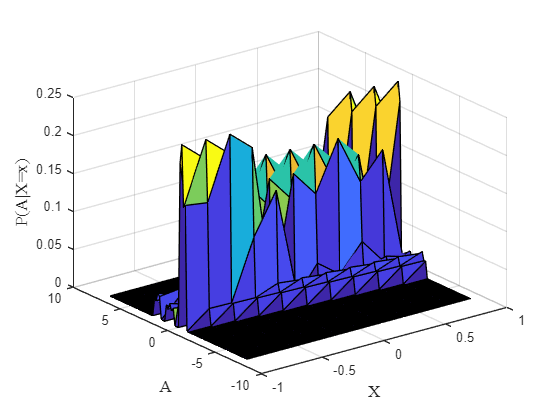

figure;
f = figure;
f.Position = [0 0 500 300];

plot(eps_grid,VarLaplace,LineWidth=2);
hold on
plot(eps_grid,VarDuchiWorst,LineWidth=2);
hold on
plot(eps_grid,VarPiecewiseWorst,LineWidth=2);
hold on
plot(eps_grid,VarHybridWorst,LineWidth=2);
hold on
plot(eps_grid,VarOptWorst,LineWidth=2);
title("Worst Variance Comparison",FontSize=13)
xlabel("epsilon",FontSize=13)
ylabel("variance",FontSize=13)
legend("Laplace Mechanism", "Duchi et al.'s solution",...
    "Piecewise Mechanism","Hybrid Mechanism","Optimal Mechanism")
grid on